# Calculation of Friction Variation

## Initialization

close all
clc

Model_Parameters;

## Data Preparation

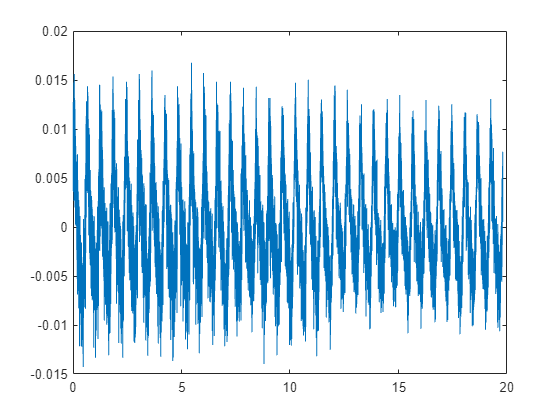

% Load Data
load("no_torque_compensation.mat");

time = data.time;

current_vec = reshape(data.signals(4).values, [], 1);   % current [A]
voltage_vec = reshape(data.signals(5).values, [], 1);   % voltage [V]
speed_vec = data.signals(2).values(:,2);                % shaft speed [rpm]
position_vec = reshape(data.signals(1).values, [], 1);  % shaft position [deg]


% Set Parameters
SAMPLE_DROP = 10/uc.Ts;      % Initial transient samples to drop
SPEED_REF = 100;            % Experiment speed [rpm]


remaining_samples = length(time) - SAMPLE_DROP;                 % # of samples after transient drop
samples_per_revolution = floor(60/(uc.Ts*SPEED_REF));           % # of samples in a shaft revolution
periods = floor(remaining_samples / samples_per_revolution);    % # of available periods in the data vector
end_index = SAMPLE_DROP + periods * samples_per_revolution;     % Index of last element


% Trim Data Vectors (remove transient, keep N revolutions/periods)
time = time(SAMPLE_DROP:end_index) - SAMPLE_DROP*uc.Ts;

current_vec = current_vec(SAMPLE_DROP:end_index);
voltage_vec = voltage_vec(SAMPLE_DROP:end_index);

% from shaft speed to motor speed, [rpm] -> [rad/s]
speed_vec = speed_vec(SAMPLE_DROP:end_index) * conv.rpm__to__rad_s / motor.gearbox;
% wrap shaft position, [deg] -> [rad]
position_vec = mod(position_vec(SAMPLE_DROP:end_index) * conv.deg__to__rad, 2*pi);


% Torque Vector Computation
torque_vec = motor.Kphi * current_vec;


% Find and Remove DC Components
current_DC = mean(current_vec);
voltage_DC = mean(voltage_vec);
speed_DC = mean(speed_vec);
torque_DC = mean(torque_vec);

current_vec = current_vec - current_DC;
voltage_vec = voltage_vec - voltage_DC;
speed_vec = speed_vec - speed_DC;
torque_vec = torque_vec - torque_DC;

% Parameters for FFT and FFT Plots
fs = 1 / uc.Ts;                 % Sampling frequency
L = length(time);               % Array length
f_axis = (0 : L-1) * fs / L;    % Frequency axis


% Debug Plots
plot(time, current_vec);

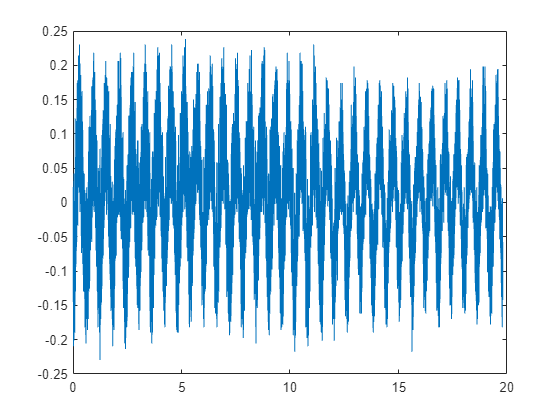

plot(time, voltage_vec)

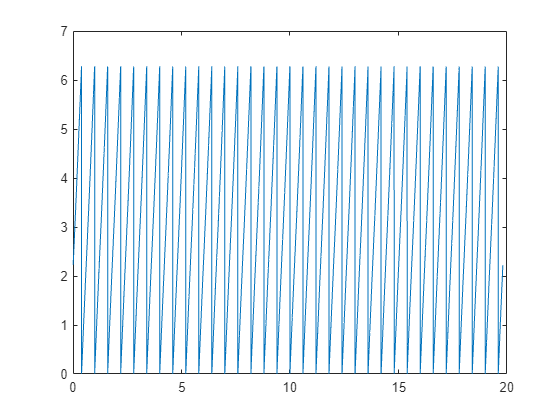

plot(time, position_vec)

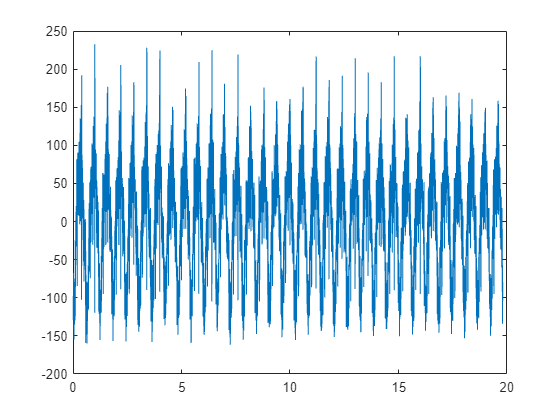

plot(time, speed_vec)

## Fourier Transform Computation and Filtering

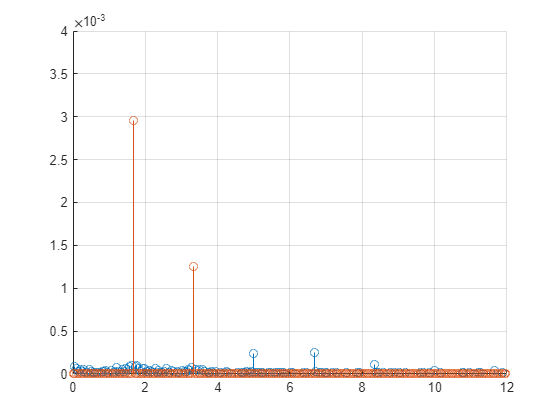

% Current
current_FFT = fft(current_vec) / L;                         % Find Fourier Transform
max_A = max(abs(current_FFT));                              % Find maximum peak
clean_current_FFT = current_FFT;
clean_current_FFT(abs(clean_current_FFT) < 0.2*max_A) = 0;  % Clear the transform

figure()
hold on
stem(f_axis, abs(current_FFT))                              % Plot result
stem(f_axis, abs(clean_current_FFT))
xlim([0 12])
ylim([0 4e-3])
grid on
hold off

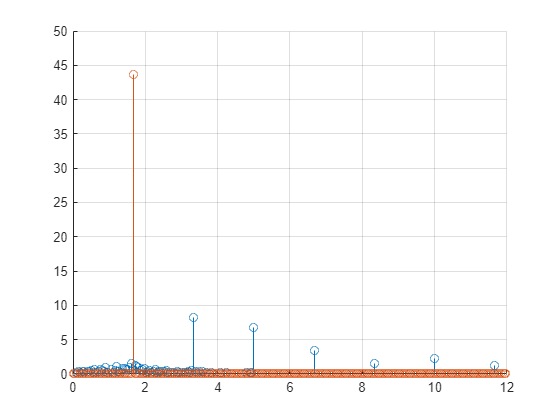

% Speed
speed_FFT = fft(speed_vec) / L;                             % Find Fourier Transform
max_W = max(abs(speed_FFT));                                % Find maximum peak
clean_speed_FFT = speed_FFT;
clean_speed_FFT(abs(clean_speed_FFT) < 0.2*max_W) = 0;      % Clear the transform

figure()
hold on
stem(f_axis, abs(speed_FFT))                                % Plot result
stem(f_axis, abs(clean_speed_FFT))
xlim([0 12])
ylim([0 50])
grid on
hold off

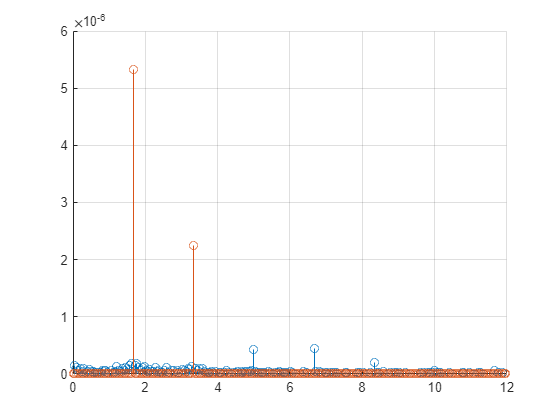

% Torque
torque_FFT = fft(torque_vec) / L;                           % Find Fourier Transform
max_T = max(abs(torque_FFT));                               % Find maximum peak
clean_torque_FFT = torque_FFT;
clean_torque_FFT(abs(clean_torque_FFT) < 0.2*max_T) = 0;    % Clear the transform

figure()
hold on
stem(f_axis, abs(torque_FFT))                               % Plot result
stem(f_axis, abs(clean_torque_FFT))
xlim([0 12])
ylim([0 6e-6])
grid on
hold off

## Inverse Fourier Transform

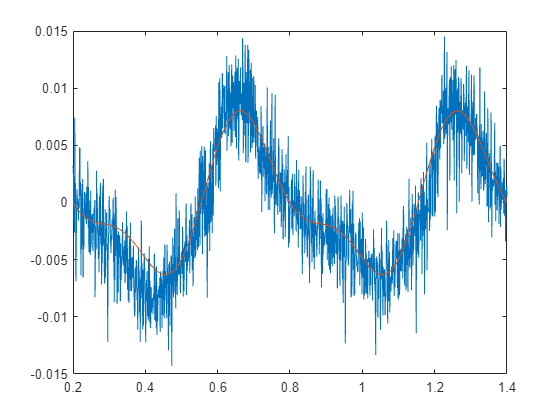

% Current
clean_current = ifft(clean_current_FFT * L);

plot(time, current_vec, time, clean_current)
xlim([0.2 2*samples_per_revolution*uc.Ts + 0.2])

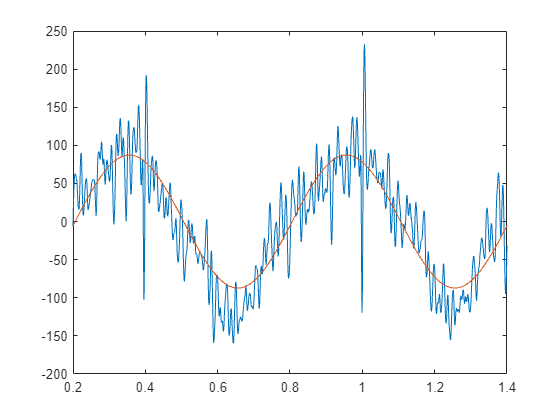

% Speed
clean_speed = ifft(clean_speed_FFT * L);

plot(time, speed_vec, time, clean_speed)
xlim([0.2 2*samples_per_revolution*uc.Ts + 0.2])

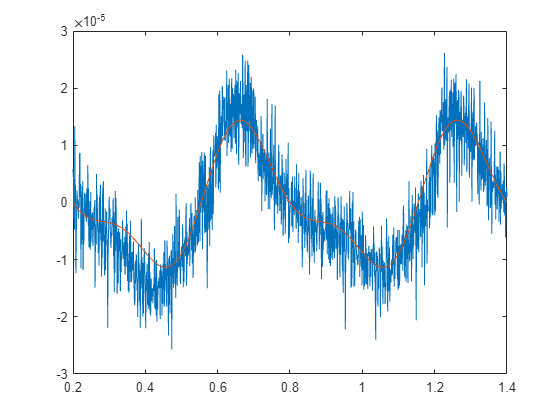

% Torque
clean_torque = ifft(clean_torque_FFT * L);

plot(time, torque_vec, time, clean_torque)
xlim([0.2 2*samples_per_revolution*uc.Ts + 0.2])

## Derivative of Speed (Acceleration) Using Fourier Transform

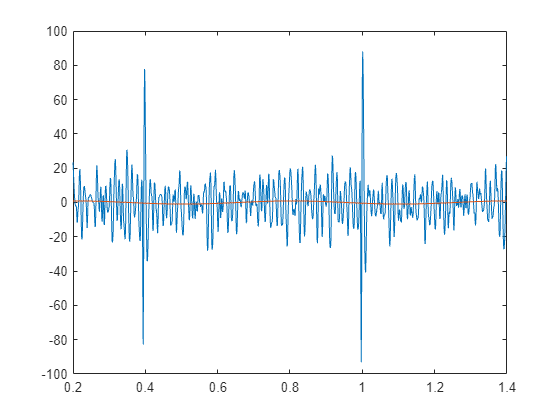

clean_acceleration_m = diff(clean_speed);
clean_acceleration_m = [clean_acceleration_m; clean_acceleration_m(1)];

acceleration_m = diff(speed_vec);
acceleration_m = [acceleration_m; acceleration_m(1)];

plot(time, acceleration_m, time, clean_acceleration_m)
xlim([0.2 2*samples_per_revolution*uc.Ts + 0.2])

## Computation of B

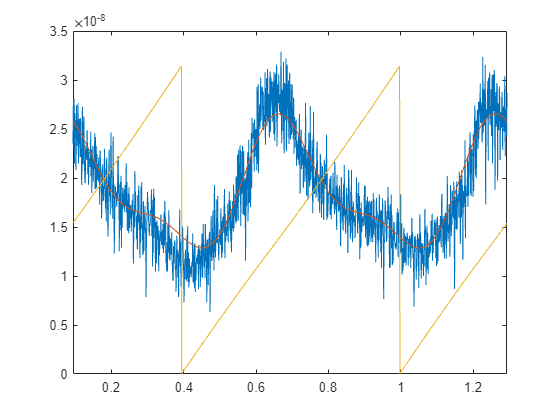

clean_torque_m = clean_torque + torque_DC;
torque_m = torque_vec + torque_DC;

clean_speed_m = clean_speed + speed_DC;
speed_m = speed_vec + speed_DC;

B_theta = (torque_m - motor.tau - motor.J*acceleration_m) ./ speed_m;
clean_B_theta = (clean_torque_m - motor.tau - motor.J*clean_acceleration_m) ./ clean_speed_m;

plot(time, B_theta, time, clean_B_theta, time, position_vec*5e-9)
xlim([0.094 2*samples_per_revolution*uc.Ts + 0.094])

mean(B_theta)

ans = 1.8697e-08

mean(clean_B_theta)

ans = 1.8681e-08

motor.B

ans = 1.4969e-08

## Coefficients of B

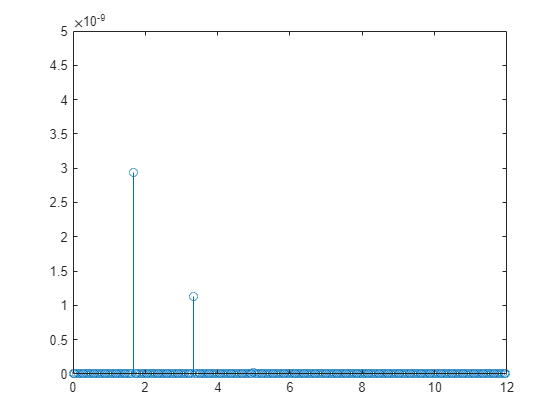

% Friction
B_FFT = fft(clean_B_theta - mean(clean_B_theta)) / L;       % Find Fourier Transform
peaks = find(abs(B_FFT) > 1e-9);
peaks = peaks(1:floor(length(peaks)/2));

stem(f_axis, abs(B_FFT))
xlim([0 12])
ylim([0 5e-9])

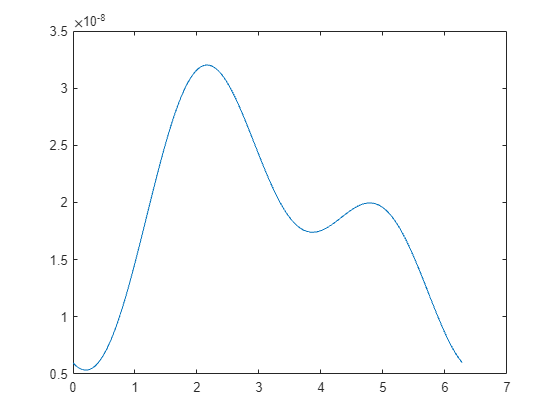

theta = [0:2*pi/1000:2*pi*0.999];
friction = 2*(4.4e-9*sin(theta - 1.1838) + 3.26e-9*sin(2*(theta - 1.1838))) + mean(clean_B_theta);

plot(theta, friction)

## Metodo alternativo

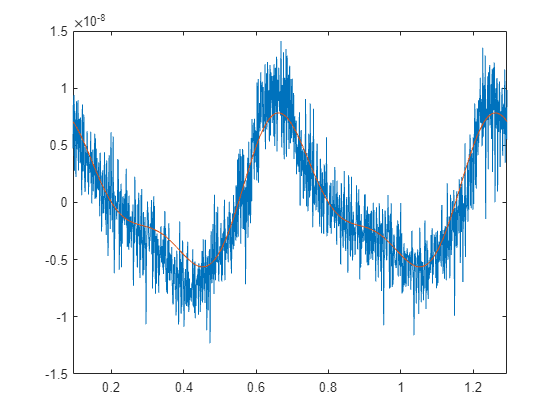

B_theta = (motor.Kphi*current_vec - motor.B*speed_vec) ./ (speed_vec + speed_DC);
clean_B_theta = (motor.Kphi*clean_current - motor.B*clean_speed) ./ (clean_speed + speed_DC);

plot(time, B_theta, time, clean_B_theta)
xlim([0.094 2*samples_per_revolution*uc.Ts + 0.094])

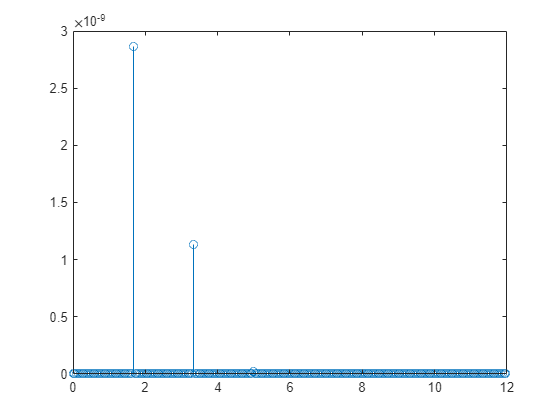

% Friction
B_FFT = fft(clean_B_theta - mean(clean_B_theta)) / L;       % Find Fourier Transform
peaks = find(abs(B_FFT) > 1e-9);
peaks = peaks(1:floor(length(peaks)/2));

stem(f_axis, abs(B_FFT))
xlim([0 12])